close all
clear
clc


c = 3e8;

## Упрощенная блок-схема велорадара

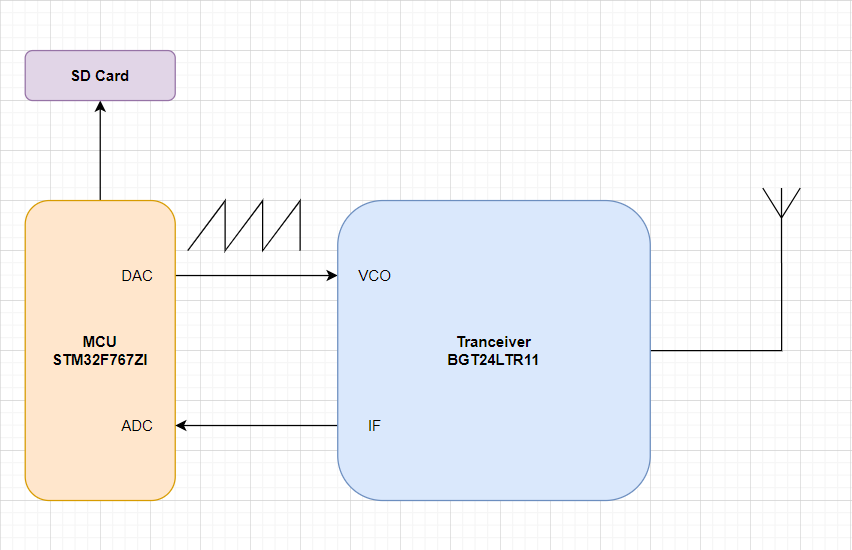

## Параметры велорадара:

Полоса ЛЧМ-сигнала

B = 100e6;

Несущяя частота

f0 = 24e9;

Период повторения импульсов (Repition Period Interval)

T = 100e-6;

Максимальная требуемая дальность

Rmax = 180;

Разрешяющяя способность по дальности

dR = c/2/B;

Чтобы обеспечить необходимую дальность, рассчитаем необходимое количество точек дя БПФ (рассматриваем реальный сигнал).

Зная частоту ПЧ на выходе трансивера, мы можем определить дальность по формуле:

 $R=\frac{f_{\mathrm{if}} \cdot c\cdot T}{2\cdot B}$                                                                                                                                                                               (1)

Максимальна частота ПЧ будет равна половине частоты Найквиста: $f_{\mathrm{if}\_\mathrm{max}} =\frac{f_s }{2}$                                                                 (2)

Зная частоту дискретизации и период повторения импульсов мы можем определить количество точек БПФ. Количество точек БПФ должно быть степени 2 (для упрощения алгоритмической части и из-за апаратных осбенностей).

$f_s \ge \frac{N_{\mathrm{fft}} }{T}\Longrightarrow f_s \ge \frac{2^n }{T}$                                                                                                                                                                      (3)

Теперб подставляя (3) в (2) и (2) в (1) получим выражение для нахождения количества точек БПФ необходимых для обеспечения максимальной дальности Rmax:

Nfft = 2^nextpow2(4*B*Rmax/c);

Теперь мы можем определить необходимую частоту дискретизации:

fs = Nfft/T;

Расстояние между сэмлами в частотной области будет равно (разрешающяя способность БПФ):

df = fs/Nfft;

Теперь подставив разрешающую способность БПФ в (1) получим реальную разрешающую способность по дальности:

dR_real = df*c*T/2/B;

Рассмотрим данную матрицу где вдоль Fast time ложаться сэмплы за один период сигнала с частотой дискретизации fs. Вдоль Slow time оси ложаться периоды сигнала на интервале когерентного наблюдения (coherent period interval)  с частотой дискретизации равной PRF (pulse repitition frequency), который определяется по следующей формуле:

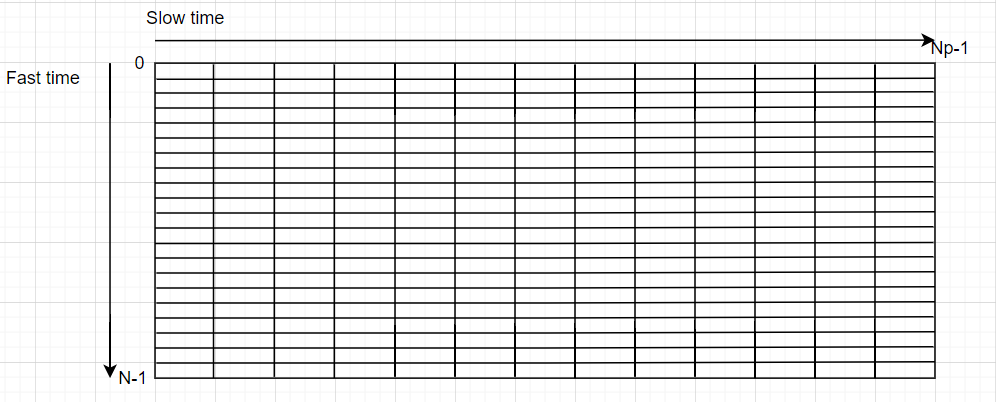

PRF = 1/T;
Np = 128;
CPI = Np*T;

Отсюда видно, что максимальная частота допплера должна быть меньше или равна частоте дискретизации вдоль slow time оси:

fd_max = PRF/2;

Из формулы для определения допплеровского смещения

$f_d =\frac{2\cdot v\cdot c}{f_0 }$                                                                                                                                                                     (4)

мы можем определить максимальную скорость (м/с):

vmax = PRF*c/4/f0;

Разрешающяя способность по скорости (м/с):

dv = vmax/Np;

## Range-Doppler signal processign

Обработка не предусматривает движение радара, то есть в даной модели радар статический!

alpha = B/T;
Fs = 2*B;
Np = 128;

Compression rate

comp = B*T;

Передающий ЛЧМ-сигнал (используеться как опорный сигнал для согласованной фильтрации)

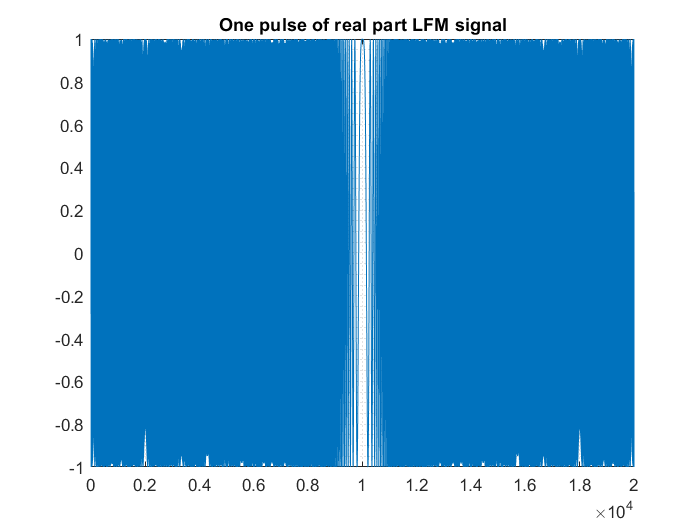

t = 0:1/Fs:Np*T-1/Fs;
N = floor(Fs*T*Np);
s_tx = exp(1i*2*pi*(-B/2*mod(t,T) + .5*alpha*mod(t,T).^2));
figure
plot(real(s_tx(1:round(Fs*T))));
title('One pulse of real part LFM signal');
grid minor

Спектр ЛЧМ-сигнала

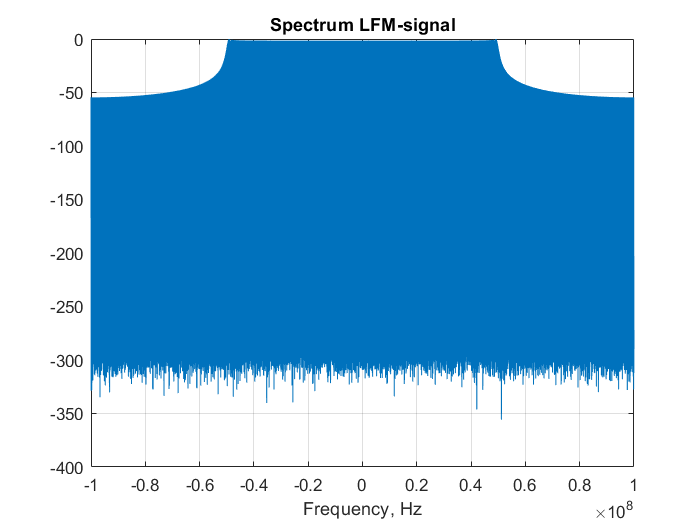

S_TX = fftshift(fft(s_tx));
S_TX_max = max(abs(S_TX));
S_TX = 10*log(abs(S_TX)) - 10*log(S_TX_max);
Ntx_fft = length(S_TX);
ff = (-Ntx_fft/2:Ntx_fft/2-1)*Fs/Ntx_fft;
figure
plot(ff, S_TX);
title('Spectrum LFM-signal');
xlabel('Frequency, Hz');
grid on

Допустим мы имеем два источника отражений, среди которых инетерсующая нас цель и отражение о земли (stationary clutter).

r = [20 100];
N_src = length(r);

И движутся со скоростями:

v = [0 15];

Перемещение за время t определяется как:

mov = v'*t;

Отсюда время задержки на распространение к цели и обратно:

td = 2*(r'-mov)/c;

Модель принятого сигнала

s = {};
for i = 1:N_src
    s{i} = exp(1i*2*pi*(-B/2*mod(t-td(i,:),T) + .5*alpha*mod(t-td(i,:),T).^2)).*exp(1i*2*pi*f0*td(i,:));
end
s_rx = zeros(1, N);
for i = 1:N_src
    s_rx = s_rx + s{i};
end

Модель принятого сигнала с шумом

SNR = 15;
%Power of transmit signal
P_tx = s_tx*s_tx'/N;
%Noise power
P_n = P_tx/10^(SNR/10);
variance = P_n;
noise = sqrt(variance)*(randn(1,N) + 1i*randn(1,N))/sqrt(2);
%Received signal with noise
s_rx_n = s_rx + noise;
%Consider only real part of the received signal
s_rx_n = real(s_rx_n);

Оценка параметров цели:

%decimation factor
df = 80;
fs_est = Fs/df;

Согласованная фильтрация

s_rx_0 = conj(s_rx_n) .* s_tx;

Децимируем наш сигнал (это аналогично что мы сэмлируем принятый сигнал на АЦП)

s_rx_decim = decimate(s_rx_0, df);
S_RX = reshape(s_rx_decim, N/Np/df, Np);

Из-за того что у нас в любом случае присутствую статические объекты, то следавательно у них будет постойянный фазовый сдвиг, а значит они будут иметь нулевое допплеровское смещение (постаянная составляющая в доплеровском спектре сигнала). Для того чтобы избавиться от этой постоянной состовляющей можно использовать метод Delay-Line Cancellers. По сути это просто ФВЧ второго и выше порядка. Из-за того что у движущихся объектов фаза меняется из-за их движения, а у статических постоянна, то мы просто можем отнять каждый последующий импульс друг от друга вдоль slow time оси, таким образом скомпенсировав постоянную составляющую.

**Структурная схема Double delay-line canceler**

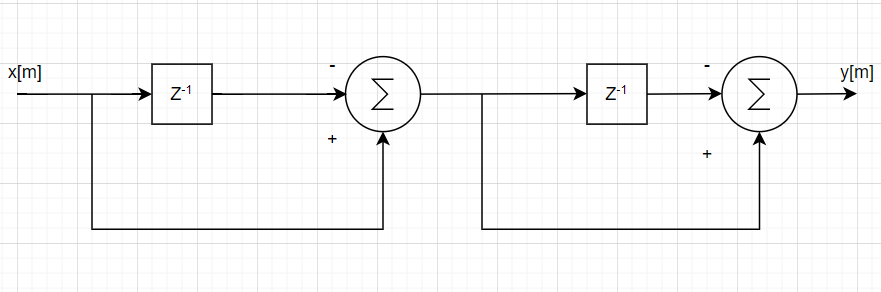

%Double delay-line canceler(needed to remove stationary clutter)
%Richards 5.2.1 Pulse Cancellers
% H(z) = 1 - 2*z^-1 + z^-2
b = [1 -2 1];
a = 1;
S_RX_canc = filter(b, a, S_RX, [], 2);

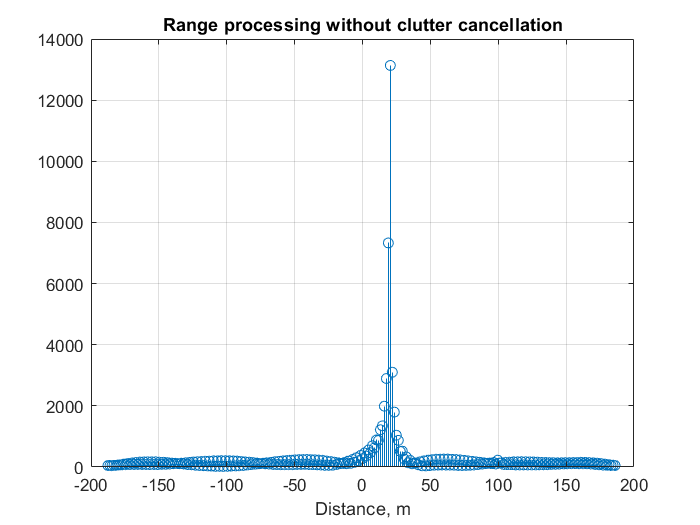

%Range processing without delay-line cancellers
Srange = fft(S_RX, Nfft, 1);
%I don't know that's true...
Srange_sum = sum(Srange,2);
[mx, indx] = max(abs(Srange_sum),[],1);
%computed distance to target
Nrfft = Nfft;
ff = (-Nrfft/2:Nrfft/2-1)*fs_est/Nrfft;
dist = ff(indx)*T*c/(2*B);

%Doppler processing without delay-line cancellers
Ndfft = Np;
Sdop = fftshift(fft(Srange, Ndfft, 2),2);
Sdop_sum = sum(Sdop,1)/Ndfft;

%Range processing with double delay-line cancellers
Srange_canc = fft(S_RX_canc, Nfft, 1);
%I don't know that's true...
Srange_sum_canc = sum(Srange_canc,2);

%Doppler processing with double delay-line cancellers
Sdop_canc = fftshift(fft(Srange_canc, Ndfft, 2),2);
Sdop_sum_canc = sum(Sdop_canc,1)/Ndfft;

%Plots
dd = ff*T*c/(2*B);
figure
stem(dd, abs(fftshift(Srange_sum)))
title('Range processing without clutter cancellation');
xlabel('Distance, m');
grid on

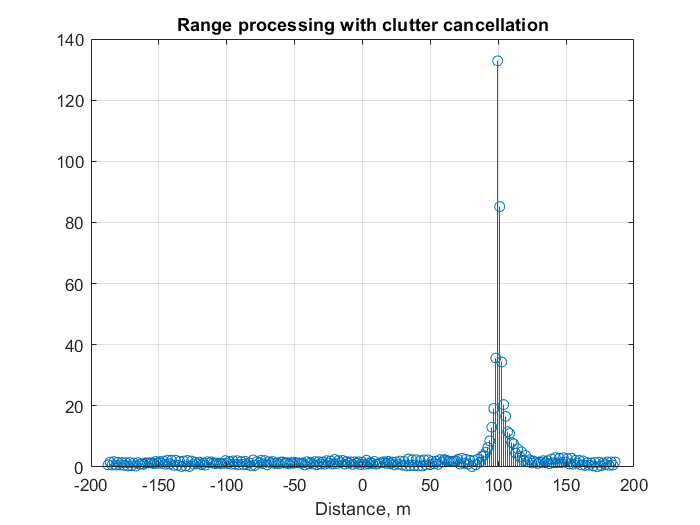


figure
stem(dd, abs(fftshift(Srange_sum_canc)))
title('Range processing with clutter cancellation');
xlabel('Distance, m');
grid on

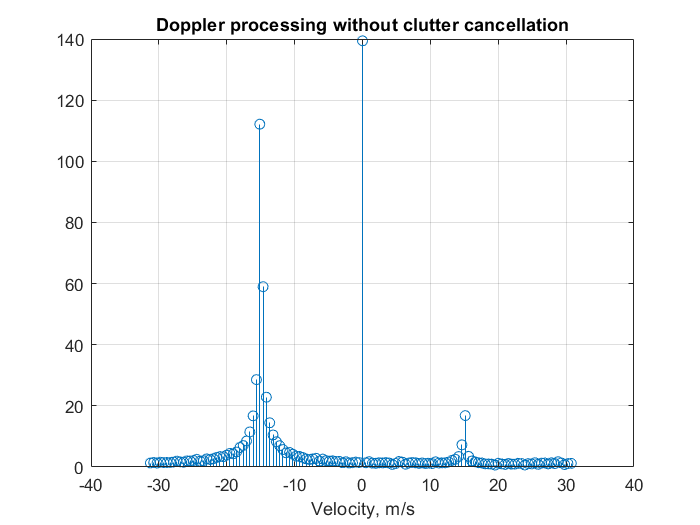


fd = (-Ndfft/2:Ndfft/2-1)*1/Ndfft/T;
vv = fd*c/(2*f0);
figure
stem(vv, abs(Sdop_sum));
title('Doppler processing without clutter cancellation');
xlabel('Velocity, m/s');
grid on

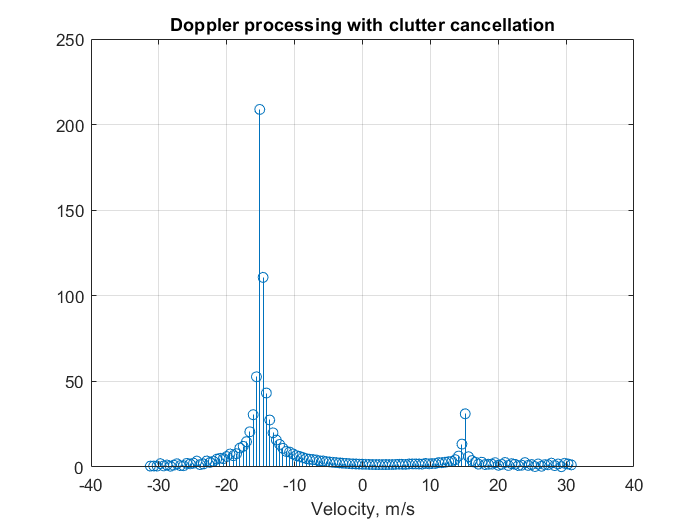


figure
stem(vv, abs(Sdop_sum_canc));
title('Doppler processing with clutter cancellation');
xlabel('Velocity, m/s');
grid on